# Gabriel Colangelo

clear
close all
clc

% Earth Parameters
mu_earth        = 398600.4415;
R_earth         = 6378.1363;

% OTV Parameters - Circular Orbit
a_otv           = 1.5*R_earth;
e_otv           = 0;
i_otv           = 0;
theta_D         = 0;

% Space Station Parameters
a_ss            = 8*R_earth;
e_ss            = 0.2;
i_ss            = 30;
RAAN_ss         = 45;
AOP_ss          = 60;
theta_A         = 240;

## Problem 2a)

Find: a, type, e, p, e, $v_D$, $\gamma_D$, $\theta^*_D$, $v_A$, $\gamma_A$, $\theta^*_A$,$|\Delta \bar{v}_D|, \alpha_D, |\Delta \bar{v}_A|, \alpha_A$

Assume: TOF = 8 hours, Type 1 transfer, mass of space station and OTV negligble. Transfer from OTV to Space Station

% Desired time of flight
TOF_A           = 8*3600;

% Orbit radius at space station arrival
r_ss            = (a_ss*(1 - e_ss^2))/(1 + e_ss*cosd(theta_A - AOP_ss));

% Direction cosine matrix from rotating frame to inertial frame
DCM_ss          =  I_DCM_R(i_ss,theta_A,RAAN_ss);

% Calculate position vectors in inertial frame
r_ss_I          = DCM_ss*[r_ss;0;0];
r_otv_I         = [a_otv;0;0];

% Calculate transfer angle (angle between position vectors)
TA              = acosd(dot(r_ss_I,r_otv_I)/(r_ss*a_otv));

% Solve Lamberts problem
probA           = LambertsProblem(TOF_A, a_otv, r_ss, TA, mu_earth);
fprintf('The semi major axis of the transfer orbit is %.2f km',probA.a)

The semi major axis of the transfer orbit is 32773.37 km


$$r_{ss} = \frac{a_{ss}(1-e_{ss}^2)}{1 + e_{ss}\cos{(\theta_{ss} - \omega_{ss})}} = 61230 \ [km] \\
[IR] =  \pmatrix{C_{\Omega} C_{\theta} - S_{\Omega} C_i S_{\theta}& -C_{\Omega} S_{\theta} - S_{\Omega} C_i C_{\theta}&
              S_{\Omega} S_i\cr S_{\Omega} C_{\theta} + C_{\Omega} C_i S_{\theta}& -S_{\Omega} S_{\theta} + C_{\theta} C_i C_{\Omega}&
              -C_{\Omega} S_i \cr S_i S_{\theta}& S_i C_{\theta}& C_i}  \\
[\bar{r}_{ss}]^I = [IR]_A [\bar{r}_{ss}]^R  = 10824 \ \hat{x} - 54120 \ \hat{y} - 26513 \ \hat{z} \ [km] \\
[\bar{r}_{OTV}]^I  = 9567 \ \hat{x} \ [km] \\
\cos{\phi} = \frac{\bar{r}_{OTV} \cdot \bar{r}_{ss}}{|\bar{r}_{OTV}||\bar{r}_{ss}|}\\
\text{Type 1: } TA = \phi = 79.82 \ [deg] \\
\\
\text{Law of cosines from space triangle: } \ c^2 = r_{ss}^2 + r_{OTV}^2 - 2r_{ss}r_{OTV}\cos{\phi} \\
\text{Semi-perimeter: } \ s = (r_{ss} + r_{OTV} + c)/2\\
\text{Minimum energy semi major axis} \ a_{min} =  s/2 = 32769 \ [km] \\
\beta_{min} = 2\sin^{-1}{\sqrt{\frac{s-c}{2a_{min}}} = 32.92 \ [deg]\\
TOF_{min} = \sqrt{\frac{a^3}{\mu}}[(\pi - \beta_{min} ) - (\sin{\pi} - \sin{\beta_{min}})] = 8.12 \ [hour]
\\

$$


**The minimum energy time of flight is greater than the desired time of flight, therefore the transfer type is an A. The transfer type is ****1A.**

For a type 1A, the true $\alpha$ and $\beta$ values are related to their principal values through:


$$\alpha = \alpha_0\\
\beta = \beta_0$$


Lamberts problem is solved numerically for $a$ using a bisection method:


$$\beta_0= 2\sin^{-1}{\sqrt{\frac{s-c}{2a}} \\
\alpha_0= 2\sin^{-1}{\sqrt{\frac{s}{2a}} \\
TOF = \sqrt{\frac{a^3}{\mu}}[(\alpha - \beta ) - (\sin{\alpha} - \sin{\beta})] = 8\ [hour] \\
\\
\underline{\mathbf{a = 32773.36 \ [km]}}$$


% Calculate semi latus rectum
p_type1     = max((4*probA.a*(probA.s - a_otv)*(probA.s - r_ss)/probA.c^2)*...
              [sin((probA.alpha + probA.beta)/2)^2, sin((probA.alpha - probA.beta)/2)^2]);
fprintf('The semi latus rectum of the transfer ellipse is %.3f km', p_type1)

The semi latus rectum of the transfer ellipse is 8054.629 km


$$\alpha  = 178.68 \ [deg] \\
\beta = 32.91 \ [deg] \\
p = a(1 - e^2) = \frac{4a(s-r_{ss})(s-r_{OTV})}{c^2}\sin^2{(\frac{\alpha \pm \beta}{2})} = 8054.63 \ \text{or} \ 7946.20 \ [km]\\
\bar{OF} = 2ae$$


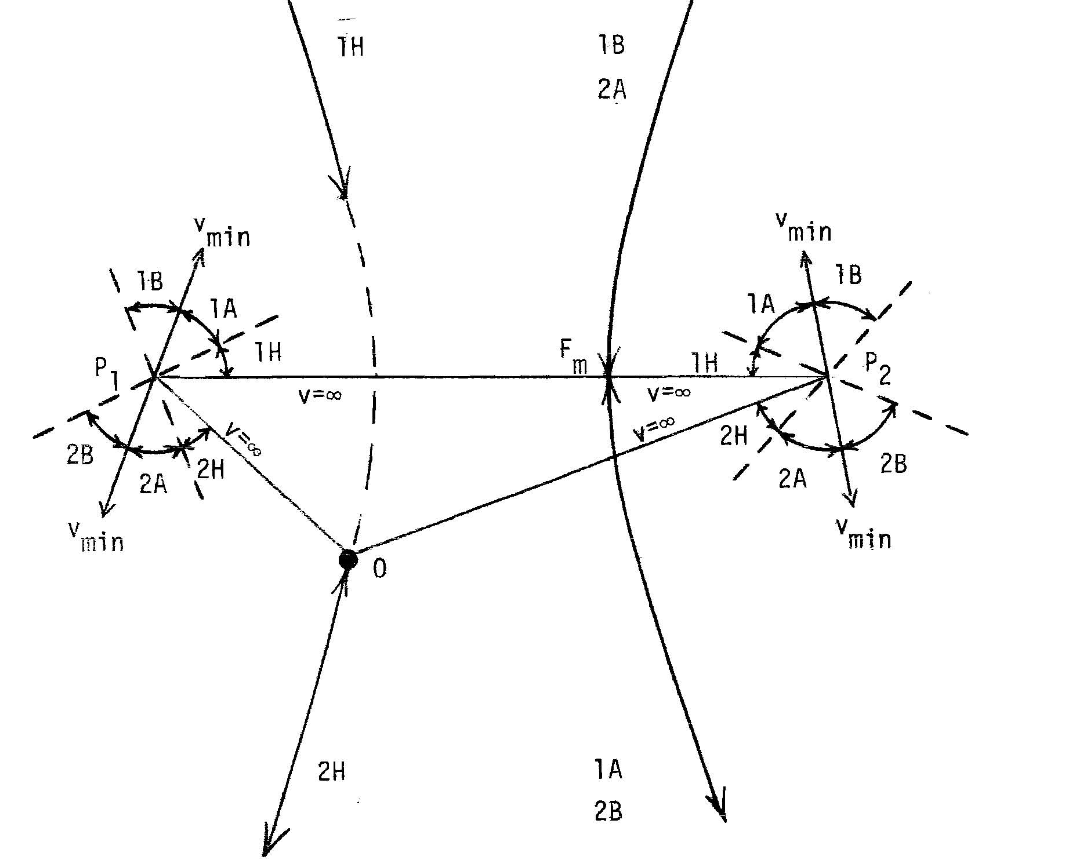

For 1A transfer type, a smaller e is needed as observed in the solution space diagram above. A smaller e will cause an increase in semi-latus rectum. Therefore, the necessary semi-latus rectum value is the larger option.


$$\underline{\mathbf{p = 8054.63 \ [km]}}$$


% Calculate eccentricity
e_type1     = sqrt(1 - p_type1/probA.a);
fprintf('The transfer eccentricity is %.4f ',e_type1)

The transfer eccentricity is 0.8685 


$$e = \sqrt{1 - \frac{p}{a}} \\
\\
\mathbf{e = 0.8685}$$


% Calculate energy of transfer ellipse
energy_type1   = -mu_earth/(2*probA.a);

% Velocity magnitude at departure
v_D            = sqrt(2*(energy_type1 + mu_earth/a_otv));
fprintf('The velocity at departure on the transfer ellipse is %.3f km/s',v_D)

The velocity at departure on the transfer ellipse is 8.436 km/s


$$r_D = r_{OTV}\\
r_A = r_{ss}\\

v_D = \sqrt{2(\frac{\mu}{r_D} - \frac{\mu}{2 a})}\\
v_D = 8.436 \ [km/s]$$


% Calculate true anomaly at departure
true_anomaly_D  = acosd((p_type1/a_otv - 1)/e_type1);

% Calculate true anomaly at arrival
true_anomaly_A  = -acosd((p_type1/r_ss - 1)/e_type1);


$$\theta^* = \cos^{-1}{(\frac{1}{e_m}(\frac{p}{r} - 1))} \\
\theta^*_D = \pm 100.49 \ [deg] \\
\theta^*_A = \pm 179.69 \ [deg] \\
\text{4 possible combinations of $\theta^*_A$ and $\theta^*_D$. However, only one pair produces a transfer angle of 79.82 deg.}\\
\text{Therefore, the pair of true anomaly's must be:} \\
\\
\mathbf{\theta^*_D = 100.49 \ [deg]}\\
\mathbf{\theta^*_A = -179.69 \ [deg]  = 180.31 \ [deg]}\\$$


% Minimum energy transfer specific angular momentum
h_type1         = sqrt(mu_earth*p_type1);

% Flight path angle at departure
gamma_D         = sign(true_anomaly_D)*acosd(h_type1/(a_otv*v_D));
fprintf('The flight path angle at departure is %.3f deg',gamma_D)

The flight path angle at departure is 45.407 deg


$$h = \sqrt{\mu p}\\
h = r_Dv_D\cos{\gamma_D}\\
\\
\gamma_D = 45.41 \ [deg] \ \ \text{Ascending based on $\theta^*_D$, so $\gamma$ > 0}$$


% Velocity magnitude at arrival
v_A            = sqrt(2*(energy_type1 + mu_earth/r_ss));
fprintf('The velocity at arrival on the transfer ellipse is %.3f km/s',v_A)

The velocity at arrival on the transfer ellipse is 0.926 km/s


$$v_A = \sqrt{2(\frac{\mu}{r_A} - \frac{\mu}{2 a})}\\
v_A = 0.926 \ [km/s]$$


% Flight path angle at arrival
gamma_A        = sign(true_anomaly_A)*acosd(h_type1/(r_ss*v_A));
fprintf('The flight path angle at arrival is %.3f deg',gamma_A)

The flight path angle at arrival is -2.025 deg


$$h = \sqrt{\mu p}\\
h = r_Av_A\cos{\gamma_A}\\
\\
\gamma_A = -2.025 \ [deg] \ \ \text{Descending based on $\theta^*_A$, so $\gamma$ < 0}$$


% F and G Equations
f           = 1 - (r_ss/p_type1)*(1 - cosd(TA));
g           = (r_ss*a_otv)*sind(TA)/h_type1;

% Departure velocity in inertial coordinates
v_D_I       = (r_ss_I - f*r_otv_I)/g;

% Initial circular orbit velocity in orbit frame
v_otv       = [0;sqrt(mu_earth/a_otv);0];

% OTV velocity in inertial frame
v_OTV_I     = I_DCM_R(0, 0, 0)*v_otv;

% Departure deltaV in intertial frame
dv_D_I      = v_D_I - v_OTV_I;
fprintf('The departure deltaV magnitude is %.4f km/s',norm(dv_D_I))

The departure deltaV magnitude is 13.4717 km/s


$$

\bar{v}_{c,otv} = \sqrt{\frac{\mu}{r_D}}\ \hat{\theta} = 6.455 \ \hat{\theta} \ [km/s] \ \text{ Prior to departure maneuver , $\hat{\theta}$ is aligned with $\hat{y}$} \\

\bar{r}_A = f \bar{r}_D + g \bar{v}_D \\
f = 1 - \frac{r_A}{p}(1 - \cos{(TA)}), \text{ where }TA = \theta^*_A - \theta^*_D. \ \ f = -5.2580 \\
g  = \frac{r_Ar_D}{\sqrt{\mu p}}\sin{(TA)} = 10175.7 \ [s]\\
\bar{v}_D = \frac{\bar{r}_A - f \bar{r}_D}{g} = 6.007 \ \hat{x} - 5.318 \ \hat{y} - 2.605 \ \hat{z} \ [km/s]\\


\Delta \bar{v}_D = \bar{v}_D - \bar{v}_{c,otv} =  6.007 \ \hat{x}  - 11.773 \ \hat{y} - 2.605 \ \hat{z} \ [km/s]\\\\
\\
\mathbf{|\Delta \bar{v}_D | = 13.47 \ [km/s]}$$


% Departure deltaV rotated into orbit frame
dv_D          = I_DCM_R(0, 0, 0)'*dv_D_I;

% Extract alpha and beta
beta_D        = asind(dv_D(3)/norm(dv_D));
alpha_D       = atan2d(dv_D(1),dv_D(2));
dv_D_VNC      = norm(dv_D)*[cosd(beta_D)*cosd(alpha_D),cosd(beta_D)*sind(alpha_D), sind(beta_D)];
fprintf('The departure maneuver alpha is %.3f deg',alpha_D)

The departure maneuver alpha is 152.967 deg


$$[\Delta \bar{v}_D]_R = [IR]_D^T [\Delta \bar{v}_D]_I \ \text{At departure point, $[IR]_D$ is the identity matrix}\\

[\Delta \bar{v}_D]_R  = 6.007 \ \hat{r}  - 11.773 \ \hat{\theta} - 2.605 \ \hat{h} \ [km/s]\\
\text{$\gamma_1$ is zero (circular orbit) \therefore $\ \hat{\theta} = \hat{V}$, $\hat{r} = \hat{C}$, and $\hat{h} = \hat{N}$}\\

[\Delta \bar{v}_D]_{VNC} = \Delta v_D[\cos{\beta_D}\cos{\alpha_D} \ \hat{V} + \cos{\beta_D}\sin{\alpha_D} \ \hat{C} + \sin{\beta_D} \ \hat{N}] =  - 11.773 \ \hat{V} +  6.007 \ \hat{C} - 2.605 \ \hat{N}\\

\beta_D = \sin^{-1}{\frac{-2.605}{\Delta v_D}} = -11.15 \ [deg]\\
\tan{\alpha_D} = \frac{\Delta v_D \cos{\beta_D}\sin{\alpha_D}}{\Delta v_D \cos{\beta_D}\cos{\alpha_D}} = \frac{6.007}{-11.773} \ \text{based off of the signs of numerator and denominator, $\alpha_D$ must be in quadrant 2.} \\
\\
\mathbf{\alpha_D = 152.97 \ [deg]}$$


% F & G equations
fdot        = (dot(r_otv_I,v_D_I)/(p_type1*a_otv))*(1 - cosd(TA)) - (1/a_otv)*(sqrt(mu_earth/p_type1))*sind(TA);
gdot        = 1 - (a_otv/p_type1)*(1 - cosd(TA));

% Velocity vector at arrival
v_A_I       = fdot*r_otv_I + gdot*v_D_I;

% Velocity in final orbit at arrival in orbit frame - at apoapsis so tangential
v_ss        = [0;sqrt(2*((-mu_earth/(2*a_ss)) + mu_earth/r_ss));0];

% Velocity in final orbit at arrival in inertial frame 
v_ss_I      = DCM_ss*v_ss;

% Arrival deltaV in intertial frame
dv_A_I      = v_ss_I - v_A_I;
fprintf('The arrival deltaV magnitude is %.4f km/s',norm(dv_A_I))

The arrival deltaV magnitude is 3.1634 km/s


$$\dot{f} = \frac{\bar{r}_D \cdot \bar{v}_D}{p r_D}[ 1 - \cos{(TA)})] - \frac{1}{r_D}\sqrt{\frac{\mu}{p}}\sin(TA) =  -1.0974 \times 10^{-4} \ [1/s] \\
\dot{g} = 1 - \frac{r_D}{p}(1 - \cos{(TA)}) = 0.0222 \\
\bar{v}_A = \dot{f} \bar{r}_D + \dot{g}\bar{v}_D =  -0.9166 \ \hat{x}  -0.1180 \ \hat{y} -0.0578 \ \hat{z} \ [km/s]\\
\bar{v}_{ss} = \sqrt{2(\frac{\mu}{r_A} - \frac{\mu}{2 a_{ss}})} \ \hat{\theta} = 2.282 \ \hat{\theta} \ \text{ At apoapsis of final orbit, therefore velocity is tangential, $\gamma_2 = 0$}\\
[\bar{v}_{ss}]_I = [IR]_A [\bar{v}_{ss}]_R = 2.0962 \ \hat{x} +  0.6987 \ \hat{y} - 0.5705 \ \hat{z} \ [km/s] \\
\Delta\bar{v}_A = [\bar{v}_{ss}]_I - [\bar{v}_A ]_I =  3.0128 \ \hat{x} +  0.8167 \ \hat{y}  -0.5127 \ \hat{z} \ [km/s] \\
\\
\mathbf{|\Delta\bar{v}_A| = 3.163 \ [km/s]}$$


% Arrival deltaV rotated into orbit frame
dv_A          = DCM_ss'*dv_A_I;

% Extract alpha and beta
beta_A        = asind(dv_A(3)/norm(dv_A));
alpha_A       = atan2d(dv_A(1),dv_A(2)) - gamma_A;
dv_A_VNC      = norm(dv_A)*[cosd(beta_A)*cosd(alpha_A),cosd(beta_A)*sind(alpha_A), sind(beta_A)];
fprintf('The arrival maneuver alpha is %.3f deg',alpha_A)

The arrival maneuver alpha is 2.621 deg


$$[\Delta \bar{v}_A]_R = [IR]_A^T [\Delta \bar{v}_A]_I \\

[\Delta \bar{v}_A]_R  =  \Delta v_A[\cos{\beta_A}\sin{\phi_A} \ \hat{r} + \cos{\beta_A}\cos{\phi_A} \ \hat{\theta} + \sin{\beta_A} \ \hat{h}] = 0.0327 \ \hat{r} + 3.1457 \ \hat{\theta} + 0.3324\ \hat{h} \ [km/s]\\
\beta_A = \sin^{-1}{\frac{0.3324}{\Delta v_A}} = 6.03 \ [deg]\\
\tan{\phi_A} = \frac{\Delta v_A \cos{\beta_A}\sin{\phi_A}}{\Delta v_A \cos{\beta_A}\cos{\phi_A}} = \frac{0.0327}{3.145}\\
\phi_A = 0.5959 \ [deg]  = \gamma_A + \alpha_A\\
\\

\mathbf{\alpha_A = 2.62 \ [deg]}$$


## Functions

function DCM = I_DCM_R(i, theta, RAAN)
    C      = @(x) cosd(x);
    S      = @(x) sind(x);
    
   DCM     = [C(RAAN)*C(theta) - S(RAAN)*C(i)*S(theta), -C(RAAN)*S(theta) - S(RAAN)*C(i)*C(theta),...
                  S(RAAN)*S(i); S(RAAN)*C(theta) + C(RAAN)*C(i)*S(theta), -S(RAAN)*S(theta) + C(theta)*C(i)*C(RAAN),...
                  -C(RAAN)*S(i);S(i)*S(theta), S(i)*C(theta), C(i)];
end